# Solutions to Exercises on Tikhonov Regularization

Course: Data Science for Engineers II

Author: Dimitar Ninevski

Date: 13.01.2025

## Prepare workspace

close all;
clear;

## Question 1

For this question, we need to load the dataset RungeTikhonov.mat. 

load RungeTikhonov.mat;

### Part a.

Performing standard polynomial approximation using a degree 15 polynomial.

degree = 15;
vFull = vander(x);
V = vFull(:, end-degree:end);
alpha = pinv(V)*y;

### Part b.

We need to add a regularization term to the second derivative of the polynomial. So first, we need to define the second derivative of the Vandermonde matrix.

d = degree:-1:1;
M = diag(d, -1);
ddV = V*M*M;

Now we need to define a lambda and find the coefficients of the regularized polynomial. The value of lambda will be obtained by trial and error.

lambda = 10^-3;
bigV = [V; sqrt(lambda)*ddV];
bigY = [y; zeros(size(ddV, 1), 1)];
alphaReg = pinv(bigV)*bigY;

### Part c.

Let's plot everything.

First we need to define the x and y values for plotting.

nrPtsPlot = 100;
xMin = min(x);
xMax = max(x);
xPlot = linspace(xMin, xMax, nrPtsPlot);
yPlot = polyval(alpha, xPlot);
yPlotReg = polyval(alphaReg, xPlot);

Now we can plot.

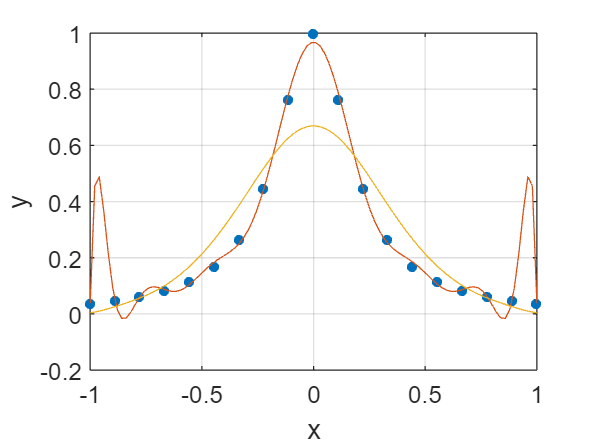

fig1 = figure;
plot(x, y, '.', 'MarkerSize', 12);
hold on
plot(xPlot, yPlot);
plot(xPlot, yPlotReg);
grid on;
xlabel('x');
ylabel('y');

### Part d.

Let's try the same thing with other values of lambda and see the differences.

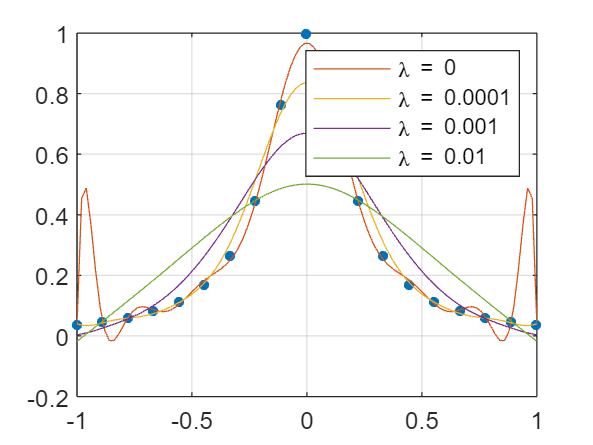

lambdas = [10^-4, 10^-3, 10^-2];
fig2 = figure;
plot(x, y, '.', 'MarkerSize', 12);
hold on;
plot(xPlot, yPlot);
legend('', '\lambda = 0');
for i = 1:length(lambdas)
    lambda = lambdas(i);
    bigV = [V; sqrt(lambda)*ddV];
    bigY = [y; zeros(size(ddV, 1), 1)];
    alphaReg = pinv(bigV)*bigY;
    yPlotReg = polyval(alphaReg, xPlot);
    plot(xPlot, yPlotReg, 'DisplayName',['\lambda = ',num2str(lambda)]);
end
legend(gca, 'show', 'Location', 'Best');
grid on;

We can see that the bigger lambda we take, the more flat the function becomes and the changes in the second derivative (changes from convex to concave, changer in curvature) are less noticeable. On the other hand, the small lambda values work pretty well at approximating the data without any oscilations. Note the differences to regularizing the first derivative instead of the second derivative.

## Question 2. 

This question is about attempting to generalize Tikhonov regularization for 2D problems.

The first part is the same as what was done before in the lecture, so I will just copy that piece of the code.

### Part a.

#### Load dataset

The data is stored in a csv file titled SingleCell_D.csv.

allData = readmatrix('SingleCell_D.csv');

Let's try and find out which row has a data where this middle cell is pressed.

[maxVal, idx] = max(allData);
[~, colMax] = max(maxVal);

On the other hand, the variable idx contains the indices of the maxima in each column. So it tells us, in which **row **is the maximum in that particular column.

rowMax = idx(colMax);

#### Extract data

The second row in the matrix contains the value from the sensors with no external pressure (other than the atmospheric pressure). We can use these as a baseline to subtract, so that our values are "zeroed" and we don't have to deal with large numbers. 

rowData = allData(rowMax, :) - allData(2, :);
rowData = rowData./max(max(rowData));

Next, we will convert the data from a row to a $6 \times 5$ matrix corresponding to the grid.

nrSensorHor = 5;
nrSensorVer = 6;
sensorData = reshape(rowData, nrSensorVer, nrSensorHor);

#### Perform unconstrained interpolation

Let's see what an unconstrained polynomial surface would look like. For easy computations, we will deifne the$x$ and$y$ values on the interval $\left\lbrack -1,1\right\rbrack$.

degX = size(sensorData, 2) - 1;
degY = size(sensorData, 1) - 1;
x = linspace(-1, 1, degX + 1);
y = linspace(-1, 1, degY + 1);

Now we can define the Vandermonde matrices and their derivatives.

Vx = vander(x);
Vy = vander(y);
%
dx = degX:-1:1;
Mx = diag(dx, -1);
dVx = Vx*Mx;
%
dy = degY:-1:1;
My = diag(dy, -1);
dVy = Vy*My;

Perform unconstrained polynomial interpolation

uncCoeffs = pinv(Vy)*sensorData*pinv(Vx');

#### Visualize the unconstrained interpolation

Because we have more sensors vertically than horizontally, I will accordingly define an appropriate number of points for visualization in both directions.

factor = 20;
xPlot = linspace(-1, 1, factor*nrSensorHor);
yPlot = linspace(-1, 1, factor*nrSensorVer);
Vxb = vander(xPlot);
Vyb = vander(yPlot);
VxPlot = Vxb(:, end-degX:end);
VyPlot = Vyb(:, end-degY:end);
%
interpSurface = VyPlot*uncCoeffs*VxPlot';

In order to visualize the interpolating surface, we will use the *imagesc* function, as well as the *surf* function.

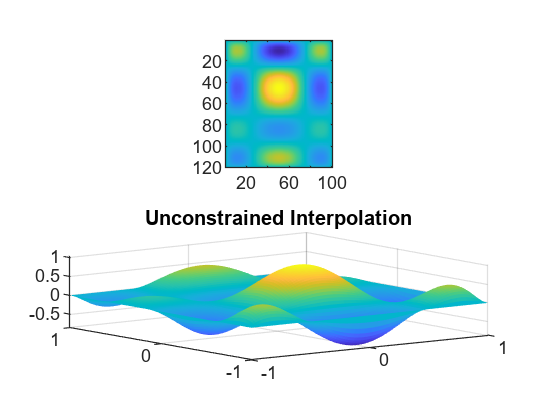

figure
subplot(2,1,1)
imagesc(interpSurface);
axis image;
subplot(2,1,2)
[xSurf, ySurf] = meshgrid(xPlot, yPlot);
surf(xSurf, ySurf, interpSurface,'EdgeColor', 'none');
title('Unconstrained Interpolation');

As we can see, in this case unconstrained interpolation doesn't provide good results due to the Runge phenomenon. 

### Part b.

We will perform Tikhonov regularization now, or attempt to at least.

We will try regularize separately in the x and y direction. There is a lot of algebra that I had to do by hand here, to get the equations right. The algebra is more or less a combination of what was done so far in the course and there is nothing new. It would be benefitial if you tried to derive the equations yourself. If you have any questions, feel free to ask.

mux = 5*10^-2;
muy = 2*10^-1;
bigMatrix = [kron(Vx, Vy);  kron(mux*dVx, Vy); kron(Vx, muy*dVy)];
bigData = zeros(size(bigMatrix,1), 1);
bigData(1:size(sensorData, 1)*size(sensorData,2)) = sensorData(:);

regCoeffsfsVec = bigMatrix\bigData;
regCoeffs = reshape(regCoeffsfsVec, size(uncCoeffs));

Now that we have computed the coefficients for the regularized surface, we can plot it.

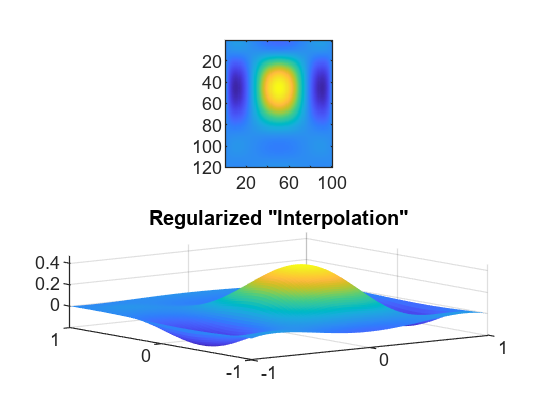

regSurface = VyPlot*regCoeffs*VxPlot';
figure
subplot(2,1,1)
imagesc(regSurface);
axis image;
subplot(2,1,2)
surf(xSurf, ySurf, regSurface,'EdgeColor', 'none');
title('Regularized "Interpolation"');

We can see that regularizing in this case also reduced the effects of the Runge phenomenon. The word "interpolation" is in quotation marks, since the surface doesn't interpolate anymore. Namely, it doesn't go through the points anymore (doesn't reach 1), but instead approximates the surface. This can be good if we are (for example) only interested in the shape, and not so much in the exact sensor values.